clear all;
% Loading workspace variables
run('load_params_estimatedValues.m');

# 2.1 Position PID–control improvements

## 1.  Anti-Windup

K_w = 2.5; % Trial & Error

#### Simulation results

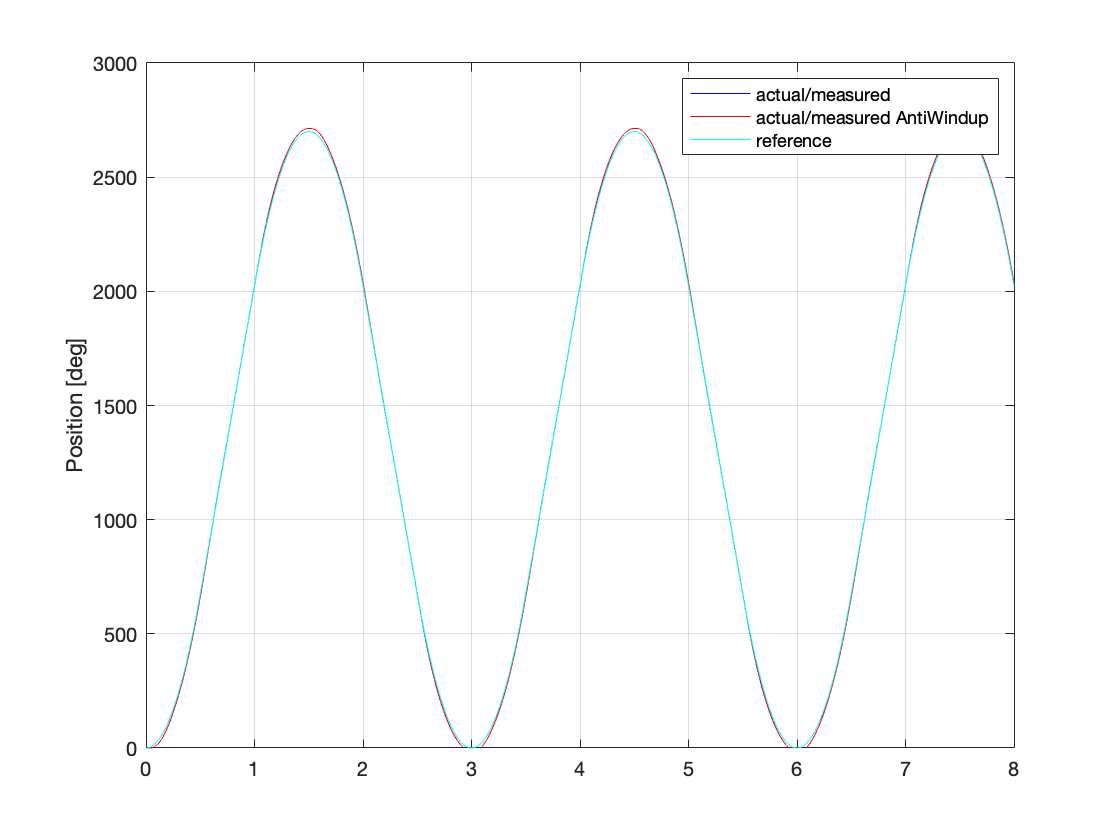

% Open Simulink model
open_system('Simulink/AntiWindup_FF.slx');

% Set parameters
set_param('AntiWindup_FF', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '8');
set_param('AntiWindup_FF/Enable Anti-Windup','Value','0');
set_param('AntiWindup_FF/Enable Feed-forward','Value','0');
set_param('AntiWindup_FF/Enable Anti-Windup1','Value','1'); % Anti-Windup ON
set_param('AntiWindup_FF/Enable Feed-forward1','Value','0');

% Run simulation
sim('AntiWindup_FF');

% Extract simulation results
AW.t = simres.time; % time vector                        
AW.thl = simres.signals(1).values(:,1); % load position
AW.thl_AW = simres.signals(1).values(:,2); % load position (AW)
AW.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(1);
plot(AW.t, AW.thl, 'b-');
hold on;
plot(AW.t, AW.thl_AW, 'r-');
hold on;
plot(AW.t, AW.thl_Ref, 'c-');
ylabel('Position [deg]');
grid on;
ylim([0,3000]);
legend('actual/measured', 'actual/measured AntiWindup', 'reference');

## 2.  Feed-Forward

#### Simulation results

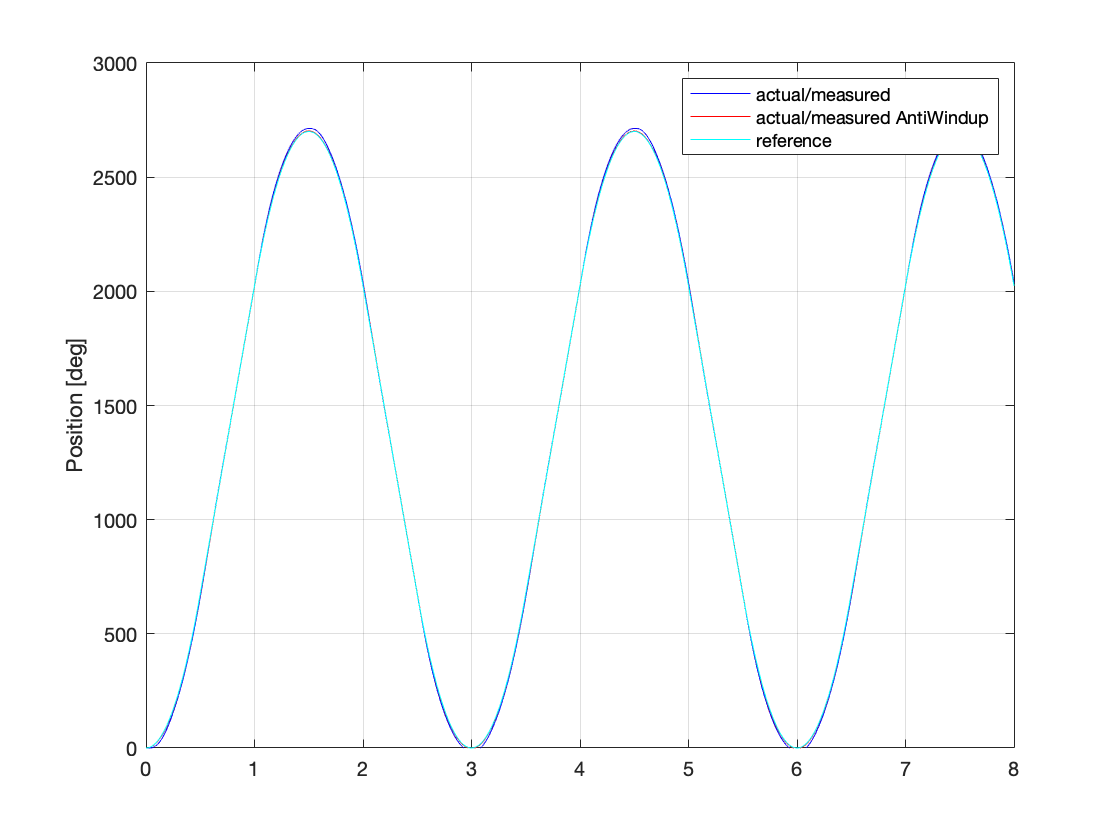

% Open Simulink model
open_system('Simulink/AntiWindup_FF.slx');

% Set parameters
set_param('AntiWindup_FF', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '8');
set_param('AntiWindup_FF/Enable Anti-Windup','Value','0');
set_param('AntiWindup_FF/Enable Feed-forward','Value','0');
set_param('AntiWindup_FF/Enable Anti-Windup1','Value','0');
set_param('AntiWindup_FF/Enable Feed-forward1','Value','1'); % Feed-Forward ON

% Run simulation
sim('AntiWindup_FF');

% Extract simulation results
FF.t = simres.time; % time vector                        
FF.thl = simres.signals(1).values(:,1); % load position
FF.thl_FF = simres.signals(1).values(:,2); % load position (AW)
FF.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(1);
plot(FF.t, FF.thl, 'b-');
hold on;
plot(FF.t, FF.thl_FF, 'r-');
hold on;
plot(FF.t, FF.thl_Ref, 'c-');
ylabel('Position [deg]');
grid on;
ylim([0,3000]);
legend('actual/measured', 'actual/measured AntiWindup', 'reference');

# 2.2 Position state–space control design

## 1.  $\bf{State-Space\  Nominal \ Control}$

% State-Space model
state_space.T_m = (simp_model.Req*est_par.J_eq)/(mot.Kt*mot.Ke + simp_model.Req*est_par.B_eq);
state_space.K_m = (drv.dcgain*mot.Kt)/(mot.Kt*mot.Ke + simp_model.Req*est_par.B_eq);

state_space.A = [0 1;0 -1/state_space.T_m];
state_space.B = [0;state_space.K_m/(state_space.T_m*gbox.N)];
state_space.C = [1 0];
state_space.D = 0;

% Nx, Nu
nominal.X = linsolve([state_space.A,state_space.B;state_space.C 0],[0;0;1]);
nominal.N_x = nominal.X(1:2,:);
nominal.N_u = nominal.X(3,:);

% Dominant Pole Approximation
mp = 0.1;
ts = 0.15;
nominal.delta = log(1/mp)/(sqrt(pi*pi + log(1/mp)*log(1/mp)));
nominal.wn = 3/(nominal.delta*ts);
nominal.Tnum = [nominal.wn^2];
nominal.Tden = [1 2*nominal.delta*nominal.wn nominal.wn^2];
nominal.T = tf(nominal.Tnum,nominal.Tden); % Dominant closed–loop dynamics approximation

% Pole placement
nominal.p1 = -nominal.delta*nominal.wn + i*nominal.wn*sqrt(1-nominal.delta^2);
nominal.p2 = conj(nominal.p1);
nominal.poles = [nominal.p1 nominal.p2];
nominal.K = place(state_space.A,state_space.B,nominal.poles);

#### Simulation results 40°

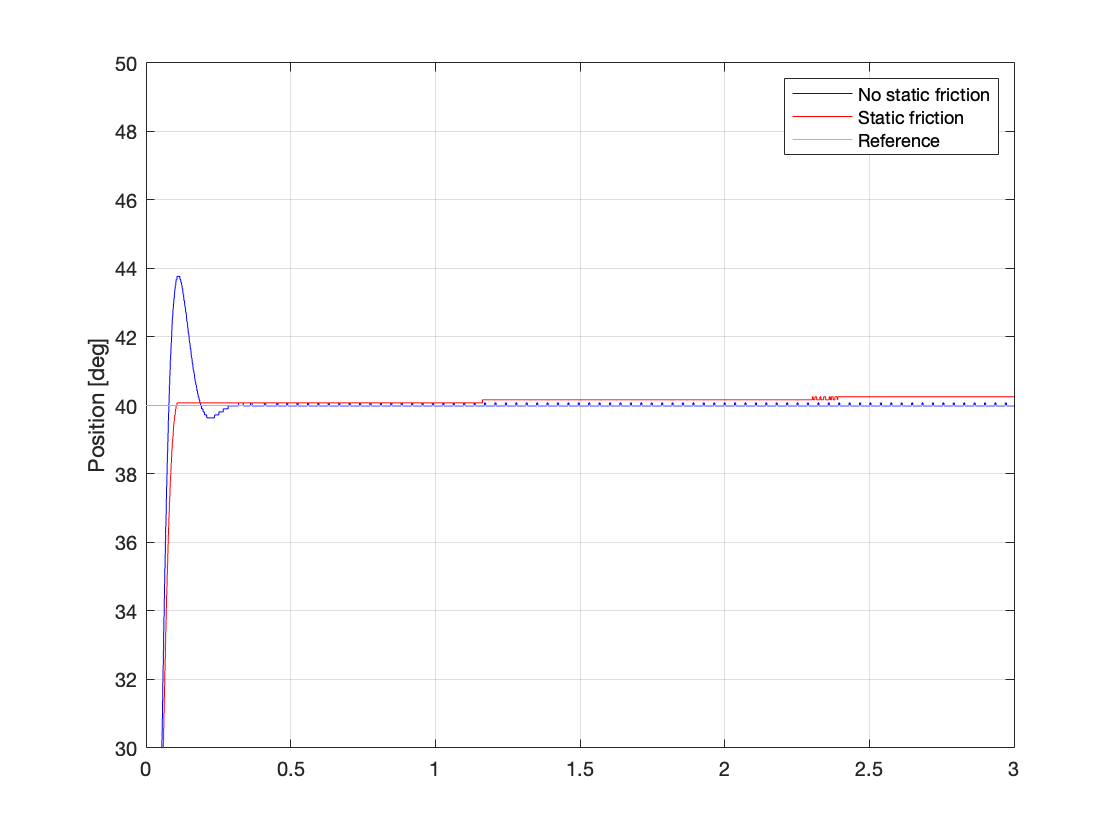

% Open Simulink model
open_system('Simulink/State_Space_Nominal.slx');

% Set parameters
set_param('State_Space_Nominal', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '3');
set_param('State_Space_Nominal/Switch1','sw','1');
set_param('State_Space_Nominal/Switch2','sw','1');
set_param('State_Space_Nominal/Switch3','sw','1');
set_param('State_Space_Nominal/Switch4','sw','1');
set_param('State_Space_Nominal/DC motor + gearbox/static','Gain','0'); % No static friction
set_param('State_Space_Nominal/DC motor + gearbox1/static','Gain','est_par.tau_sf'); % Static friction

% Run simulation
sim('State_Space_Nominal');

% Extract simulation results
nominal.t = simres.time; % time vector                        
nominal.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
nominal.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
nominal.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(2);
plot(nominal.t, nominal.thl_nsf, 'b-');
hold on;
plot(nominal.t, nominal.thl_sf, 'r-');
hold on;
plot(nominal.t, nominal.thl_Ref, 'c-');
ylabel('Position [deg]');
grid on;
ylim([30,50]);
legend('No static friction', 'Static friction', 'Reference');

#### Simulation results 70°

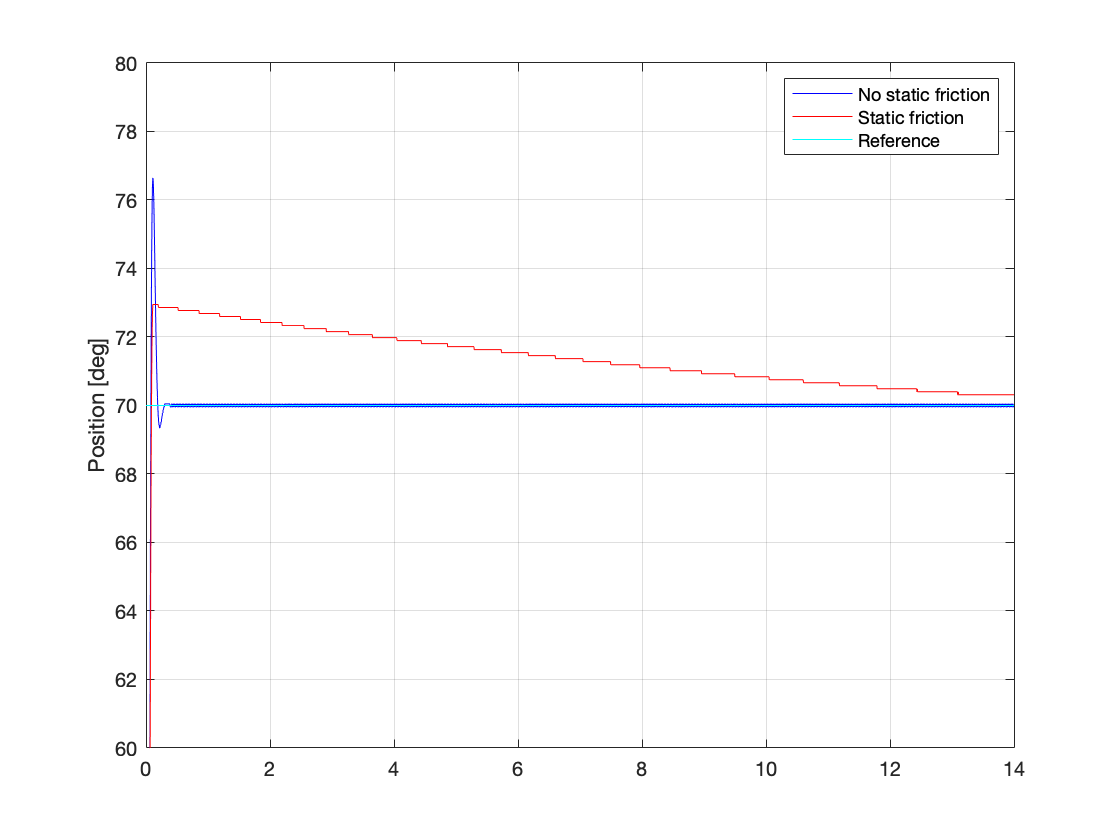

% Open Simulink model
open_system('Simulink/State_Space_Nominal.slx');

% Set parameters
set_param('State_Space_Nominal', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '14');
set_param('State_Space_Nominal/Switch1','sw','0');
set_param('State_Space_Nominal/Switch2','sw','1');
set_param('State_Space_Nominal/Switch3','sw','0');
set_param('State_Space_Nominal/Switch4','sw','1');
set_param('State_Space_Nominal/DC motor + gearbox/static','Gain','0'); % No static friction
set_param('State_Space_Nominal/DC motor + gearbox1/static','Gain','est_par.tau_sf'); % Static friction

% Run simulation
sim('State_Space_Nominal');

% Extract simulation results
nominal.t = simres.time; % time vector                        
nominal.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
nominal.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
nominal.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(3);
plot(nominal.t, nominal.thl_nsf, 'b-');
hold on;
plot(nominal.t, nominal.thl_sf, 'r-');
hold on;
plot(nominal.t, nominal.thl_Ref, 'c-');
ylabel('Position [deg]');
grid on;
ylim([60,80]);
legend('No static friction', 'Static friction', 'Reference');

#### Simulation results 120°

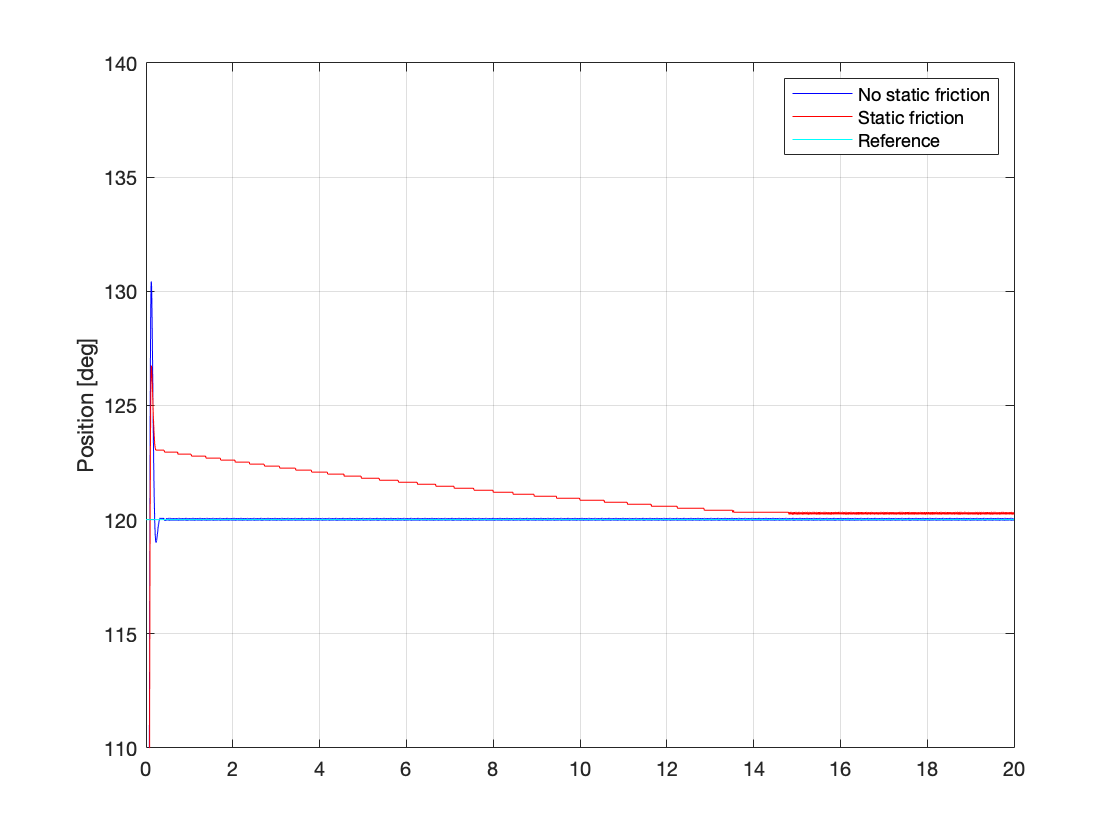

% Open Simulink model
open_system('Simulink/State_Space_Nominal.slx');

% Set parameters
set_param('State_Space_Nominal', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '20');
set_param('State_Space_Nominal/Switch1','sw','0');
set_param('State_Space_Nominal/Switch2','sw','0');
set_param('State_Space_Nominal/Switch3','sw','0');
set_param('State_Space_Nominal/Switch4','sw','0');
set_param('State_Space_Nominal/DC motor + gearbox/static','Gain','0'); % No static friction
set_param('State_Space_Nominal/DC motor + gearbox1/static','Gain','est_par.tau_sf'); % Static friction

% Run simulation
sim('State_Space_Nominal');

% Extract simulation results
nominal.t = simres.time; % time vector                        
nominal.thl_nsf = simres.signals(1).values(:,1); % load position (no static friction)
nominal.thl_sf = simres.signals(1).values(:,2); % load position (static friction)
nominal.thl_Ref = simres.signals(1).values(:,3); % load position reference

% Plot simulation results
figure(4);
plot(nominal.t, nominal.thl_nsf, 'b-');
hold on;
plot(nominal.t, nominal.thl_sf, 'r-');
hold on;
plot(nominal.t, nominal.thl_Ref, 'c-');
ylabel('Position [deg]');
grid on;
ylim([110,140]);
legend('No static friction', 'Static friction', 'Reference');

## 2.  $\bf{State-Space\  Robust \ Control \ (Integral \ 
 action)}$

% Augmented state-space
robust.Ae = [0 state_space.C;[0;0] state_space.A];
robust.Be = [0;state_space.B];
robust.Ce = [0 state_space.C];

% Real and imaginary parts of the eigenvalues in (6) (in the assignment 1)
robust.sigma = -nominal.delta*nominal.wn;
robust.wd = nominal.wn*sqrt(1-nominal.delta^2);
% Pole placement
robust.poles1 = [robust.sigma + i*robust.wd, robust.sigma - i*robust.wd, robust.sigma];
robust.poles2 = [robust.sigma, robust.sigma, robust.sigma];
robust.poles3 = [2*robust.sigma + i*robust.wd, 2*robust.sigma - i*robust.wd, 2*robust.sigma];
robust.poles4 = [2*robust.sigma + i*robust.wd, 2*robust.sigma - i*robust.wd, 3*robust.sigma];

robust.K1 = place(robust.Ae,robust.Be,robust.poles1);
robust.K2 = acker(robust.Ae,robust.Be,robust.poles2);
robust.K3 = place(robust.Ae,robust.Be,robust.poles3);
robust.K4 = place(robust.Ae,robust.Be,robust.poles4);
robust.K1

ans =   160.3478   13.6210    0.2338


robust.K2

ans =    56.0358    8.4054    0.2338


robust.K3

ans =   656.9105   38.8371    0.6541


robust.K4

ans =   985.3658   50.0443    0.7942
